# Support Vector Machines (SVM) Model: MUSIC-Linear

## Setup:

**Configurate the path and clear the workspace, etc.**

clc; close all; clear;
addpath(genpath(fullfile('../')));

## Input model:

***The input features are described as the power levels found at each frequency bin***

% IR Set with Duration = 1000ms
fs = 44100;
IRLen = 40;
dir = "aux_data/IR_Z_fixed/2s/"; % Azimuth
nameIRms = "IR44K_2s_1000ms";
IRms = struct2cell(load(dir+nameIRms));
IRms = IRms{1};
IRms =IRms(:,2);
IRms = [IRms{:}];

nfft = 512;
p = 6;     % Signal Subspace dimensions
N_bins = 1+ nfft/2;

df = fs/(2*((nfft/2)+1));
f = 0:df:(fs-df)/2;
f_20k = ceil(20000/(fs/(N_bins*2)));

N_noise_samples = 10;
N_augmentations = N_noise_samples*IRLen;% 100 noise samples * 40 augmentations = 4000 augmented samples

x_train = zeros(N_bins,N_augmentations);
y_train = zeros(N_augmentations,1);
vec = [1:6, 36:40; 6:16; 16:26; 26:36];
designSpecs = fdesign.lowpass('Fp,Fst,Ap,Ast', 20000, 22050, 0.01, 80, fs);
F = design(designSpecs);
for k = 1:N_noise_samples
    for i = 1:40
        % Augment noise sample
        noise = randn(fs,1);
        noise = filter(F,noise);
        index = ((k-1)*40) + i;
        noise_aug = conv(noise, IRms(:,i), 'same');
        
        [Pxx, ~] = pmusic(noise_aug,p, nfft);
        x_train(:,index) = normalize(Pxx, 'range');  
        y_train(index) = find(any(i==vec,2),1);
    end
end
directions = ["Front"; "Left"; "Back"; "Right"];
y_train = categorical(directions(y_train));

***Train***

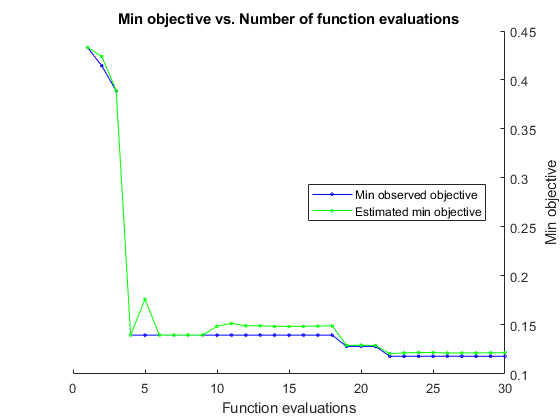

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Coding | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |     0.43338 |     0.32197 |     0.43338 |     0.43338 |     onevsone |       247.46 |       495.68 |
|    2 | Best   |     0.41444 |     0.27999 |     0.41444 |     0.42391 |     onevsall |       282.29 |       780.78 |
|    3 | Best   |     0.38889 |     0.30545 |     0.38889 |     0.38924 |     onevsone |       1.4474 |       5.3531 |
|    4 | Best   |      0.1397 |      51.189 |      0.1397 |     0.13972 |     onevsall |      0.31416 |    0.0011221 |
|    5 | Accept |     0.23851 |     0.44428 |   

% Rename variables for clarity:
%   X: Predictor data (rows are observations)
%   Y: Response data
X = x_train'; 
Y = y_train;

% Ensemble template 
tTree = templateTree('surrogate','on');
tEnsemble = templateEnsemble('GentleBoost',100,tTree);

Mdl = fitcecoc(X,Y,'Coding',"onevsall",'Learners','svm', "Prior","uniform", "OptimizeHyperparameters","auto",...
    "HyperparameterOptimizationOptions",struct('AcquisitionFunctionName','expected-improvement-plus'));

## Evaluation

% Compute resubstitution classification error to obtain training error 
train_error = resubLoss(Mdl, 'lossfun', 'classiferror');
disp("Training error: " + train_error*100 + "%");

Training error: 1.5278%


% Cross-validate classifier
CVMdl = crossval(Mdl);
% Compute cross-validation classification error: 
cv_error = kfoldLoss(CVMdl, 'lossfun','classiferror');

disp("Validation error: " + cv_error*100 + "%");

Validation error: 11.9369%


***Case 1: Low errors***

***    If the validation error is higher than the training error this indicates that there is a case of HIGH VARIANCE***

***    High variance can be solved by adding more training data***

***Case 2: High errors***

***    If both the validation and training error are high this indicates a case of HIGH BIAS***

***    High bias asks for more distinct features***

## Test on same reverberation duration

***Augment test samples***

N_tests = 10;
N_augmentations = N_tests*IRLen;% 100 noise samples * 40 augmentations = 4000 augmented samples

x_test = zeros(N_bins,N_augmentations);
y_test = zeros(N_augmentations,1);

for k = 1:N_tests
    for i = 1:40
        % Augment noise sample
        noise = randn(fs,1);
        noise = filter(F,noise);
        index = ((k-1)*40) + i;
        noise_aug = conv(noise, IRms(:,i), 'same');
        
        [Pxx, ~] = pmusic(noise_aug,p, nfft);
        x_test(:,index) = normalize(Pxx, 'range');
        y_test(index) = find(any(i==vec,2),1);
    end
end
directions = ["Front"; "Left"; "Back"; "Right"];
y_test = categorical(directions(y_test));

***Predict test samples***

y_pred = predict(Mdl,x_test');
y_pred(randsample(numel(y_pred),5))

ans = 5×1 categorical array
     Back 
     Front 
     Front 
     Right 
     Back 


%numMisclass = sum(~strcmp(,species(idxVal)));
test_error = 1-sum(y_pred==y_test)/N_augmentations;
disp("Test error: " + test_error*100 + "%");

Test error: 10%
